PID Control - Ziegler-Nichols, SP 35 -> 50

clear model;
filename='PID_control_ZN_SP_50.csv'

filename = 'PID_control_ZN_SP_50.csv'

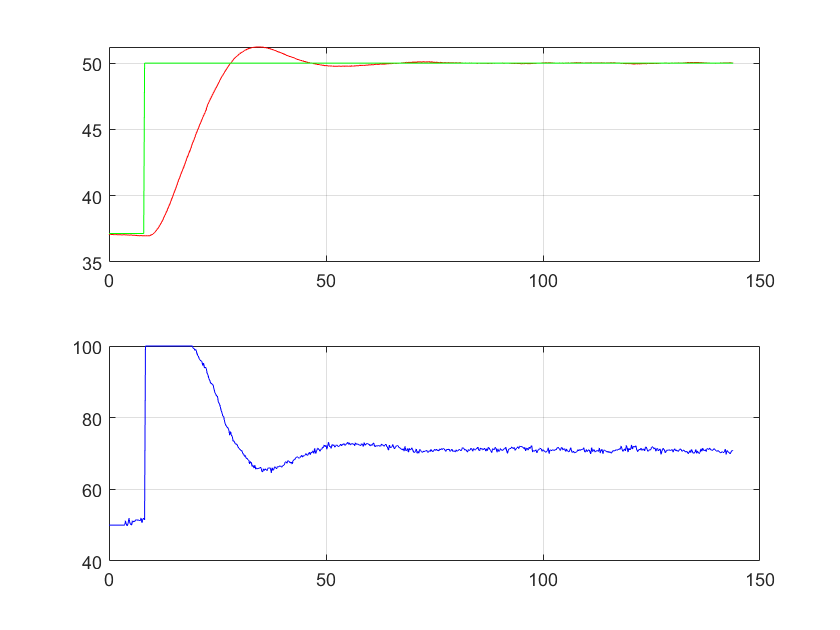

Tp=0.2;
[model.timeUTC model.sp model.pv model.cv model.orifice model.resistance model.ds3] = csvimport(filename, 'columns', {'UTC Time','SP', 'PV', 'CV', 'DS1', 'DS2', 'DS3'});
model.time(1)=0;
for i=2:length(model.timeUTC)
   model.time(i,1)=Tp*(i-1);
end

PID_SP_50=model;

figure;
subplot(2,1,1)
plot(PID_SP_50.time,PID_SP_50.pv,'red');
grid on;
hold on
plot(PID_SP_50.time,PID_SP_50.sp,'green');
subplot(2,1,2)
plot(PID_SP_50.time,PID_SP_50.cv,'blue');
grid on;

PID Control - Ziegler-Nichols, Resistance Disturbance

clear model;
filename='PID_control_ZN_D_resistance.csv'

filename = 'PID_control_ZN_D_resistance.csv'

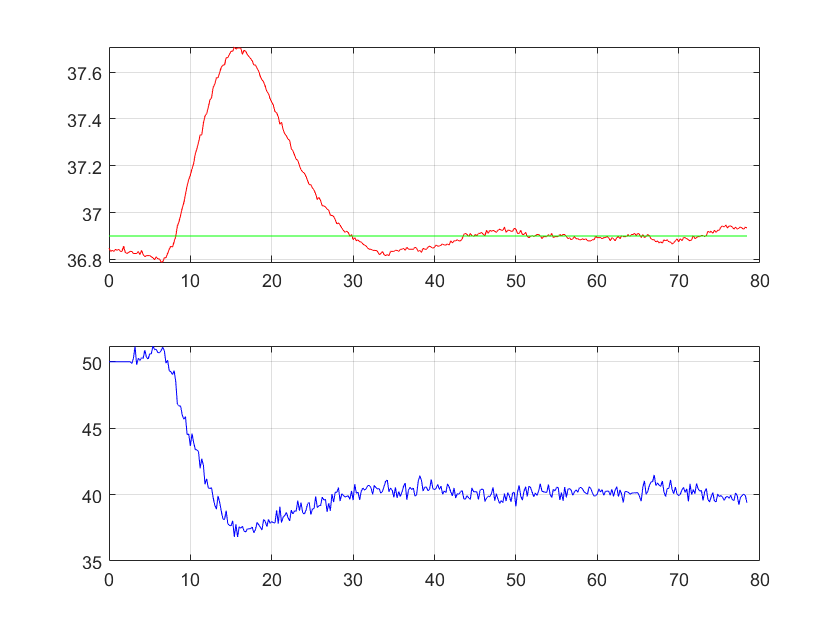

Tp=0.2;
[model.timeUTC model.sp model.pv model.cv model.orifice model.resistance model.ds3] = csvimport(filename, 'columns', {'UTC Time','SP', 'PV', 'CV', 'DS1', 'DS2', 'DS3'});
model.time(1)=0;
for i=2:length(model.timeUTC)
   model.time(i,1)=Tp*(i-1);
end

PID_dist_res=model;

figure;
subplot(2,1,1)
plot(PID_dist_res.time,PID_dist_res.pv,'red');
grid on;
hold on
plot(PID_dist_res.time,PID_dist_res.sp,'green');
subplot(2,1,2)
plot(PID_dist_res.time,PID_dist_res.cv,'blue');
grid on;

PID Control - Ziegler-Nichols, Orifice Disturbance

clear model;
filename='PID_control_ZN_D_orifice.csv'

filename = 'PID_control_ZN_D_orifice.csv'

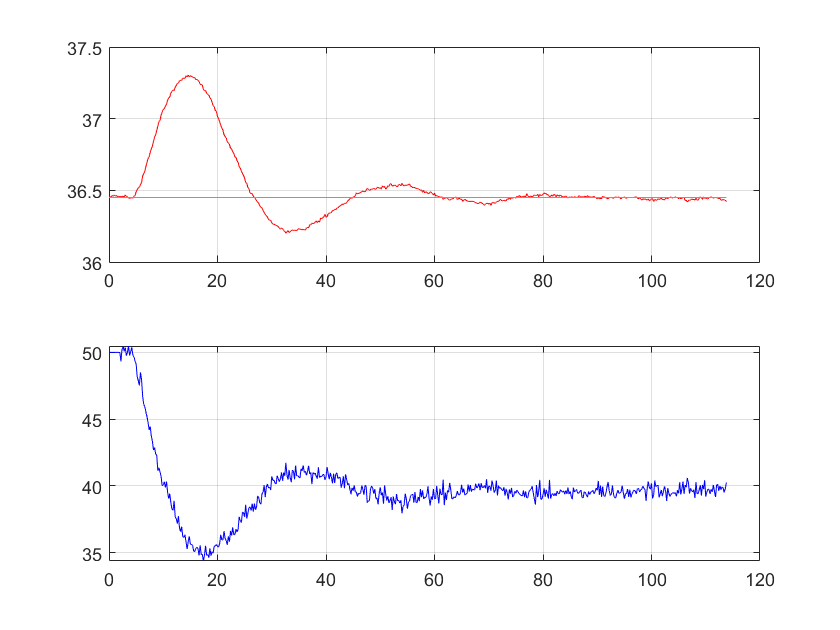

Tp=0.2;
[model.timeUTC model.sp model.pv model.cv model.orifice model.resistance model.ds3] = csvimport(filename, 'columns', {'UTC Time','SP', 'PV', 'CV', 'DS1', 'DS2', 'DS3'});
model.time(1)=0;
for i=2:length(model.timeUTC)
   model.time(i,1)=Tp*(i-1);
end

PID_dist_ori=model;

figure;
subplot(2,1,1)
plot(PID_dist_ori.time,PID_dist_ori.pv,'red');
grid on;
hold on
plot(PID_dist_ori.time,PID_dist_ori.sp,'green');
subplot(2,1,2)
plot(PID_dist_ori.time,PID_dist_ori.cv,'blue');
grid on;